%{
ES115 - Class-Project Module: Elevator Motion Profile
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-26

Purpose:
    - To simulate the motion of an elevator using acceleration, constant velocity, and deceleration phases.
    - To model realistic elevator movement using piecewise motion logic.
    - To evaluate ride smoothness based on velocity and acceleration changes.

Input:
    - Total simulation time and time step
    - Acceleration and deceleration rates (m/s^2)
    - Maximum (cruise) velocity (m/s)
    - Duration of each motion phase (acceleration, cruise, deceleration)

Output:
    - Velocity vs time plot showing all motion phases
    - Position vs time plot showing elevator displacement
    - Visualization of smooth transitions between motion phases

Engineering Algorithms:
    - Define time vector with fixed step size
    - Implement piecewise motion:
        * Acceleration phase: velocity increases linearly
        * Cruise phase: constant velocity
        * Deceleration phase: velocity decreases linearly
    - Integrate velocity to obtain position over time
    - Ensure continuity between phases (no sudden jumps)
    - Plot velocity and position curves for analysis
    - Assess smoothness based on slope changes in velocity

MATLAB tools/functions:
    - vector operations
    - plot, xlabel, ylabel, title, legend, grid
    - for-loops or logical indexing
    - cumulative sum (cumsum) for position
    - linspace or colon operator for time vector
    - figure
%}

%{
ES115 - Class-Project Module: Elevator Motion Profile
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-26
%}

clear; clc; close all;   
% Clears old data, command window, and closes any open plots



% Parameters

dt = 0.01;              
% Time step (how often we update calculations)
% Smaller dt = smoother/more accurate simulation

t_total = 10;           
% Total time the elevator moves (seconds)

t = 0:dt:t_total;       
% Time vector from 0 to 10 seconds

a = 1;                  
% Acceleration (m/s^2)
% How quickly the elevator speeds up

v_max = 3;              
% Maximum velocity (m/s)
% The cruising speed of the elevator

t_accel = v_max / a;    
% Time needed to reach max velocity
% Derived from v = a*t → t = v/a

t_decel = t_accel;      
% Time to slow down (assumed symmetric)

t_cruise = t_total - t_accel - t_decel;  
% Remaining time spent at constant speed



% Storage Arrays

v = zeros(size(t));     
% Velocity array (starts at 0 everywhere)

x = zeros(size(t));     
% Position array (starts at 0)


% Piecewise Motion logic

% We loop through time and decide which phase we are in

for k = 1:length(t)
    
    if t(k) < t_accel
       
        % ACCELERATION PHASE
        
        % Velocity increases linearly from 0 to v_max
        % Formula: v = a*t
        v(k) = a * t(k);
        
    elseif t(k) < (t_accel + t_cruise)
        
        % CRUISE PHASE
        % Elevator moves at constant speed
        v(k) = v_max;
        
    elseif t(k) <= t_total
       
        % DECELERATION PHASE      
        % Elevator slows down to a stop
        % Velocity decreases linearly
        v(k) = v_max - a*(t(k) - t_accel - t_cruise);
    end
    
end

% Position Calculation
% cumsum = cumulative sum (adds values step-by-step)
x = cumsum(v) * dt;

% Acceleration Calculation
acc = [0 diff(v)/dt];
% diff(v) finds change between velocity points
% divide by dt to get acceleration


% Plotting Results
figure;
%subplot sets up 3 sets of axes in succession
% Velocity Plot
subplot(3,1,1)
plot(t, v, 'b', 'LineWidth', 2)
ylabel('Velocity (m/s)')
title('Elevator Motion Profile')
grid on


% Straight line up = accelerating
% Flat line = constant speed
% Line down = slowing down

%Position Plot ----
subplot(3,1,2)
plot(t, x, 'r', 'LineWidth', 2)
ylabel('Position (m)')
grid on

% Curve gets steeper = speeding up
% Straight line = constant speed
% Curve flattens = slowing down

%Acceleration Plot
subplot(3,1,3)
plot(t, acc, 'k', 'LineWidth', 1.5)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
grid on

% Flat positive = speeding up
% Zero = cruising
% Flat negative = slowing down


% Smoothness Analysis

% Smooth ride means acceleration changes gradually

max_acc = max(abs(acc));

fprintf('Maximum acceleration: %.2f m/s^2\n', max_acc);

Maximum acceleration: 1.00 m/s^2



% If acceleration changes suddenly, uncomfortable ride (jerk)


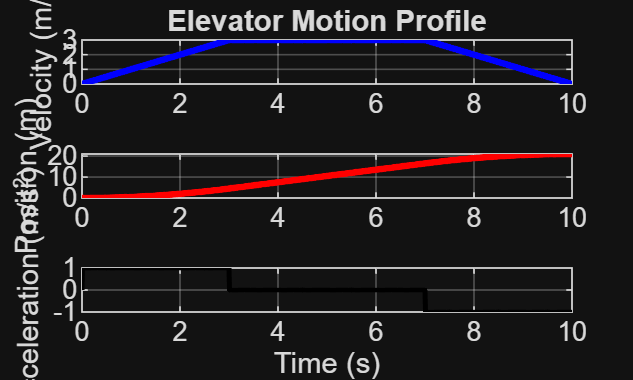

% Export graph
% Saves your plot as a high-quality image
exportgraphics(gcf, 'elevator_motion.png', 'Resolution', 300);